pX = MATERIAL.CT/B/2/1e5/pi;

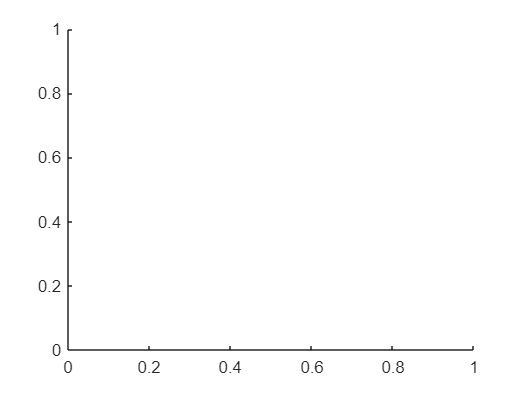

fig(1) = figure;
ax(1) = axes;

clear cr cri pic
% cr = zeros(incident.n,nmode);
legendText = [];

for ii = 1:incident.n
	tmp = cT{ii};
	nmode = length(tmp);
	for imode = 1:nmode
		cr(ii,imode) = tmp(imode);
	end
end


for imode = 1:nmode
	idx = find(cr(:,imode));
	iff = K(idx);
	ict = cr(idx,imode);
	ffi = linspace(min(iff),max(iff),250);
	cri(:,imode) = interp1(iff,ict,ffi,'spline');

	ffi = ffi*pX;

	if imode == incident.mode
		pic(imode) = plot(ffi,cri(:,imode),SeriesIndex=imode,LineWidth=1.5);
		legendText = [legendText;convertCharsToStrings(['第', num2str(imode-1), '阶模态*'])];
		hold on
	else
		pic(imode) = plot(ffi,cri(:,imode),SeriesIndex=imode,LineWidth=1.5);
		legendText = [legendText;convertCharsToStrings(['第', num2str(imode-1), '阶模态'])];
		hold on
	end
end

错误使用 matlab.internal.math.interp1
插值要求每个网格维度至少有两个采样点。

出错 interp1 (第 188 行)
        VqLite = matlab.internal.math.interp1(X,V,method,method,Xqcol);

hold off
grid on
legend(legendText,'Location','northeast')
xlim([min(K*pX),max(K*pX)])

a1 = gca;
a1.XAxis.LineWidth = 1.5;
a1.YAxis.LineWidth = 1.5;
a1.XAxis.FontSize = 14;
a1.YAxis.FontSize = 14;
a1.XLabel.FontSize = 18;
a1.YLabel.FontSize = 16;

idx1 = find(cr(:,1));
idx2 = find(cr(:,2));
iff1 = K(idx1);
iff2 = K(idx2);
cr1 = cr(idx1,1);
cr2 = cr(idx2,2);

smoothedData1 = smoothdata(cr1,"movmean","SmoothingFactor",0.25,SamplePoints=iff1);
smoothedData2 = smoothdata(cr2,"movmean","SmoothingFactor",0.25,SamplePoints=iff2);

fig(2) = figure;
ax(2) = axes;
% plot(iff1,cr1,"Color",[77 190 238]/255,"DisplayName","输入数据")
plot(iff1,smoothedData1,"Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","平滑数据")
hold on
plot(iff2,smoothedData2,"Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","平滑数据")
hold off
grid on

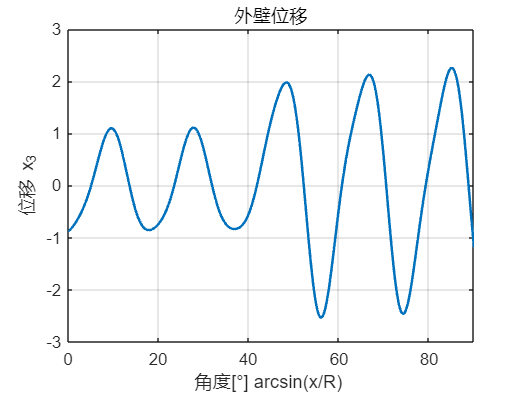

UT = real(U_s_T(end,:));
X = linspace(0,1,length(UT))*90;
plot(X,UT,LineWidth=1.5)
ylim([-3 3])
xlim([0 90])
grid on
title("外壁位移")
xlabel(" 角度[°] arcsin(x/R)  ")
ylabel("位移 x_3")

UB = U_s_B(end,:);
X = linspace(0,1,length(UB));
plot(real(UB(1,:)))